# part one

s =tf("s");
G =(666.3)/(s^3+250.2*s^2+29.74*s-4033);
num = [666.3];
den = [1 250.2 29.74 -4033];
sys = tf(num,den);
margin(num,den);
[Gm,Pm,Wcp,Wcg] = margin(sys);

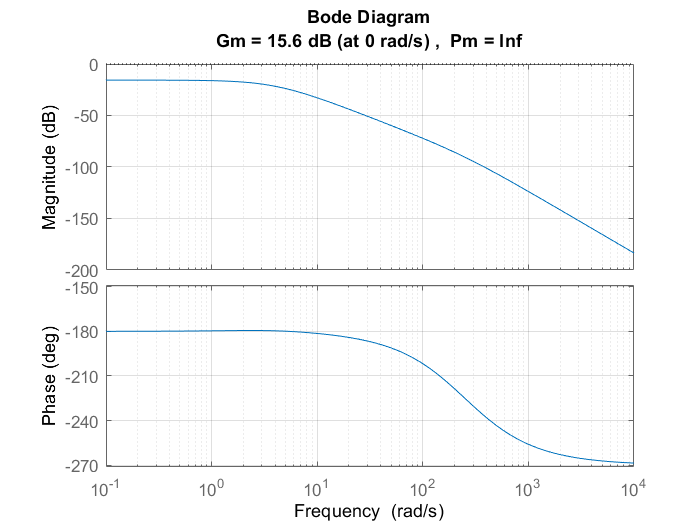

grid;

## part two

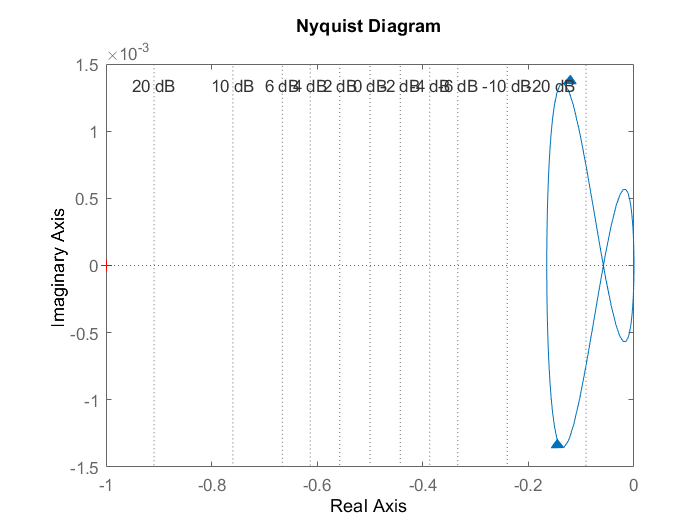

num = [666.3];
den = [1 250.2 29.74 -4033];
nyquist(num,den);
grid;

## part three

zeta = 0.4

zeta = 0.4000

wn= 300

wn = 300

wg =wn*(-2*zeta^2+(1+4*zeta^2)^0.5)^0.5

wg = 294.0344



Gpd =1/(wg/100)*s+1

Gpd =
 
  0.3401 s + 1
 
Continuous-time transfer function.



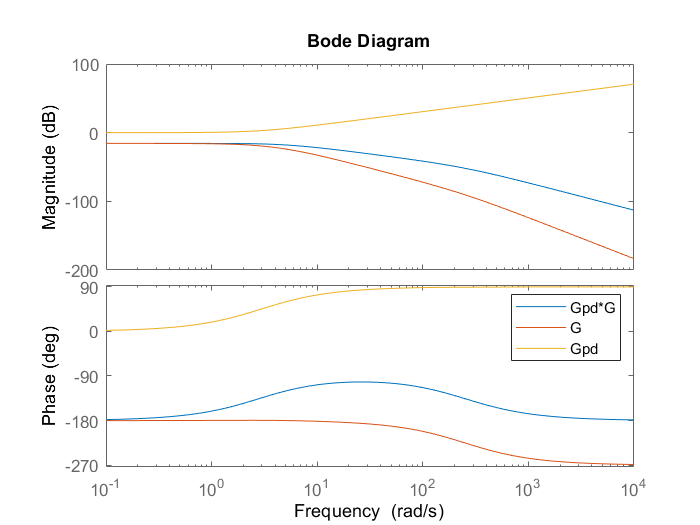


bode(Gpd*G,G,Gpd)
legend('Gpd*G','G','Gpd')

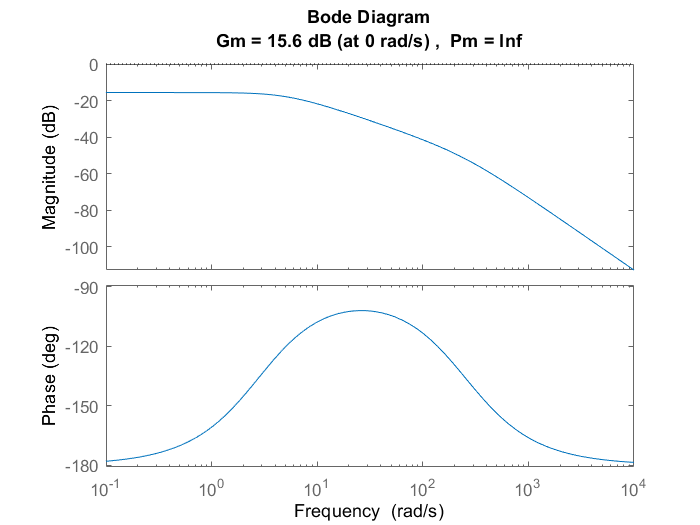


margin(Gpd*G)



K=10^(54/20)

K = 501.1872

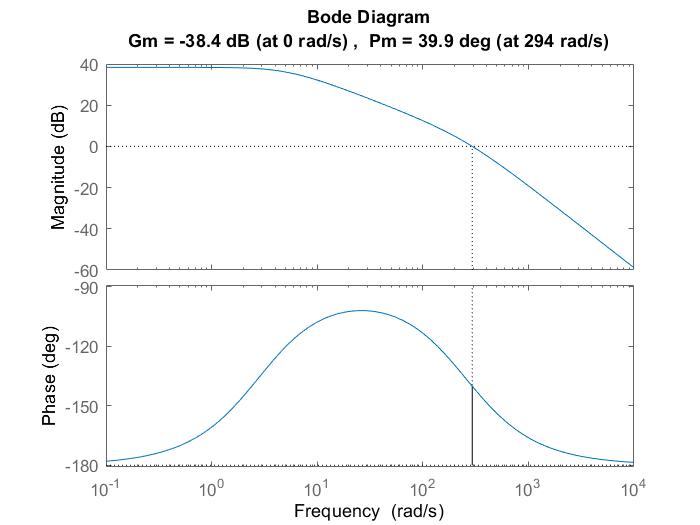

margin(K*Gpd*G)

Gpi=((s)+wg/1000)/s;
Gpid = K*Gpi*Gpd

Gpid =
 
  170.5 s^2 + 551.3 s + 147.4
  ---------------------------
               s
 
Continuous-time transfer function.



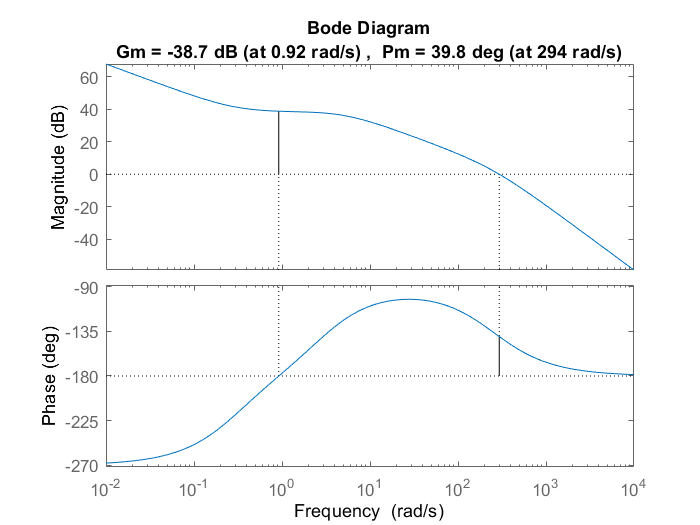

margin(Gpid*G);

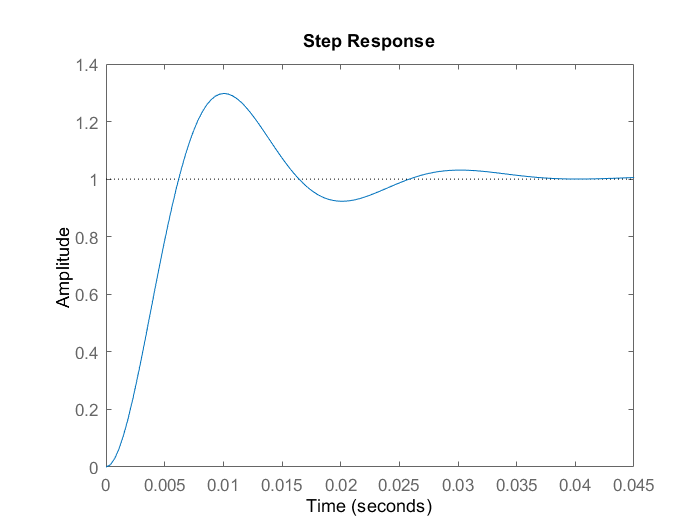


step(feedback(Gpid*G,1));

stepinfo(feedback(Gpid*G,1))

ans = struct with fields:
        RiseTime: 0.0042
    SettlingTime: 0.0337
     SettlingMin: 0.9231
     SettlingMax: 1.2976
       Overshoot: 29.7641
      Undershoot: 0
            Peak: 1.2976
        PeakTime: 0.0101


Part  4

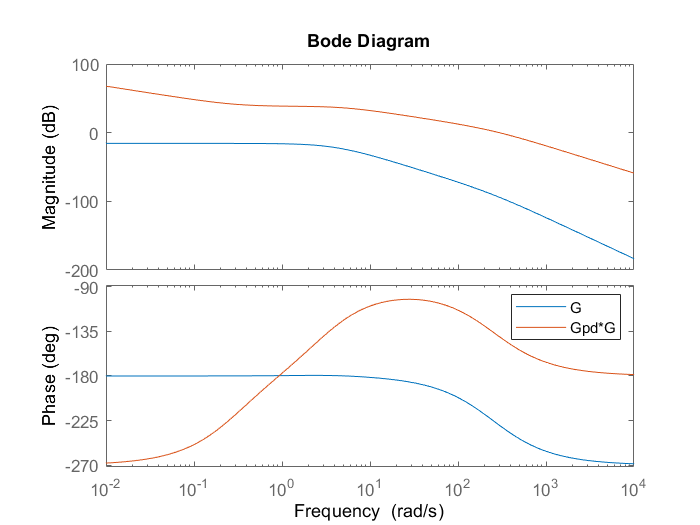

bode(G,Gpid*G)
legend('G','Gpid*G')

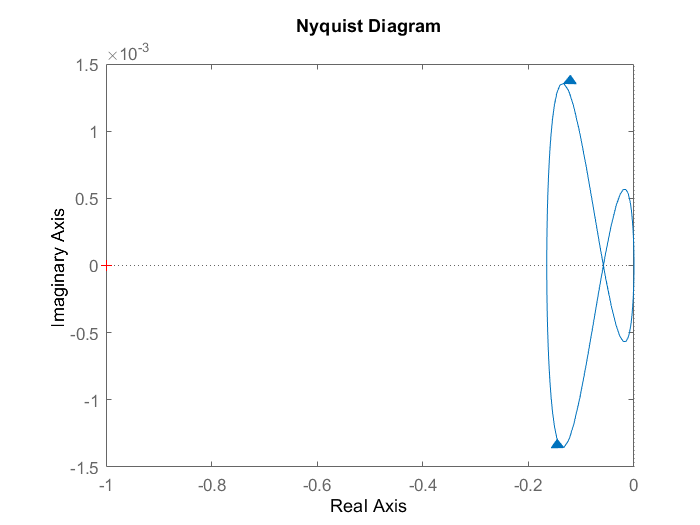

nyquist(G)

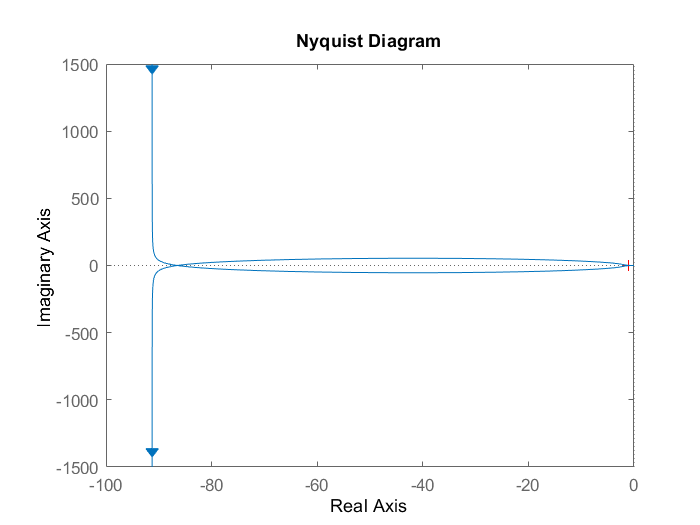

nyquist(Gpid*G)